# Identifying a 2D SSM for an oscillator chain

This is an example of how to reconstruct a slow 2D SSM of a mechanical system using synthetic measurements of the full state space. 

In this example, we consider a damped oscillator chain with an additional nonlinear spring attached to the leftmost mass. The measurements for this example are transients occurring from exact initial conditions on the slow 2D SSM.

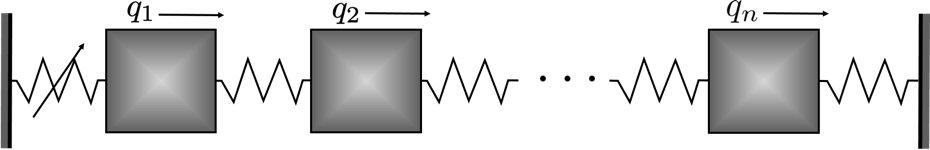

clearvars
close all

## Example setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) 
= \mathbf{0}$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $n\times n$ mass, stiffness, and damping matrices, respectively.

We rewrite the system in first-order form as


$$\mathbf{\dot{y}} = \mathbf{A}\mathbf{y} + \mathbf{G}(\mathbf{y}) = \mathbf{F}(\mathbf{y})$$


with

$\mathbf{y}=\left[\begin{array}{c}\mathbf{q}\\\dot{\mathbf{q}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}\mathbf{0}  & \mathbf{I}\\-\mathbf{M}^{-1}\mathbf{K} & -\mathbf{M}^{-1}\mathbf{C} \end{array}\right],\quad\mathbf{G}(\mathbf{y})=\left[\begin{array}{c}  \mathbf{0} \\ -\mathbf{M}^{-1}\mathbf{f}(\mathbf{y})\end{array}\right]$.

n         = 5;      % number of masses
mass      = 1;
mass1     = 1.5;
stiffness = 1;
dampingM   = 0.002;
dampingK   = 0.005;

vMass = ones(1,n);
M = mass*diag(vMass); M(1,1) = mass1;
K = stiffness*(2*eye(n) ...
    - diag(ones(1,n-1),-1) ...
    - diag(ones(1,n-1),1));
K(end,end) = 1;
C = dampingM*M + dampingK*K;

The nonlinearities are not necessarily physical, but are chosen as 


$$f_1 \left(q_1 ,\dot{\;q_1 } \right)=0\ldotp 33{\dot{\;q_1 } }^2 +3q_1^3 +0\ldotp 7q_1^2 \dot{\;q_1 } +0\ldotp 5{\dot{\;q_1 } }^3$$


% nonlinearities: f1 = 0.33*q1dot^2 + 3*q1^3 + 0.7*q1^2*q1dot + 0.5*q1dot^3
F2 = sptensor(zeros(n, 2*n, 2*n)); F3 = sptensor(zeros(n, 2*n, 2*n, 2*n));
F2(1,n+1,n+1) = 0.33;    % q1dot^2
F3(1,1,1,1) = 3;         % q1^3
F3(1,1,1,n+1) = 0.7;     % q1^2*q1dot 
F3(1,n+1,n+1,n+1) = 0.5; % q1dot^3
fnl = {F2*mass1, F3*mass1};
[F, lambda, E, G] = functionFromTensors(M, C, K, fnl);


## Generation of Synthetic Data

Having set up the dynamics of the problem, we now move on to generate synthetic data, which will be used to fit a parametrisation of the manifold. We will divide the data into a training set, for model fitting, and a test set, for validation.

nTraj = 2;
indTest = [1];
indTrain = setdiff(1:nTraj, indTest);

**We need to ensure that the gathered data actually approximates the SSM!**

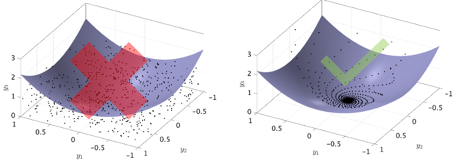 

### **Let us initialize trajectories close to the SSM**

Since we know the equations of the system, we may prepare ICs along the slowest subspace of the linearization. These are initial conditions of the form


$$c_1 \textrm{Real}\left({\mathit{\mathbf{v}}}_1 \right)+$$

$$c_2 \mathrm{Imag}\left({\mathit{\mathbf{v}}}_1 \right)$$


rng(0); var = 1;
initial_coeffs = var * randn(2, nTraj);
IC = real(E(:,1)).*initial_coeffs(1,:) + imag(E(:,1)).*initial_coeffs(2,:);

The data is generated by time-integration of the right-hand side of the system. In this case we are observing the full state space, so the `observable` function is the identity.

observable = @(x) x;
slowTime = 2*pi/abs(lambda(1));
nPeriods = 140; 
nDataPerPeriod = 50;
endTime = nPeriods * slowTime;
nSamp = nDataPerPeriod * nPeriods + 1;
dt = endTime/(nSamp-1);
tic
yData = integrateTrajectories(F, endTime, IC, nSamp, observable);

simulating trajectory 1 of 2...
simulating trajectory 2 of 2...


toc

Elapsed time is 0.256186 seconds.


## Plot generated trajectory data

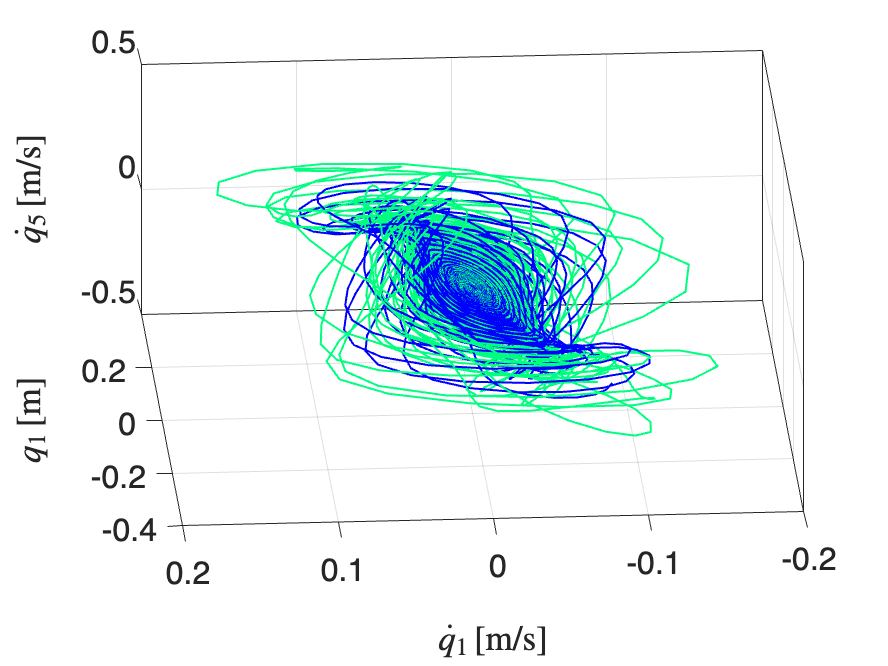

customFigure(); colororder(winter(nTraj));
for iTraj = 1:size(yData,1)
    plot3(yData{iTraj,2}(1,:), yData{iTraj,2}(n+1,:), yData{iTraj,2}(2*n,:),'Linewidth',1,'Displayname',['Trajectory ' num2str(iTraj)])
end
xlabel('$q_1 \, [$m$]$','Interpreter','latex'); 
ylabel('$\dot{q}_1 \, [$m/s$]$','Interpreter','latex'); 
zlabel(['$\dot{q}_{' num2str(n) '} \, [$m/s$]$'],'Interpreter','latex'); 
view(3)

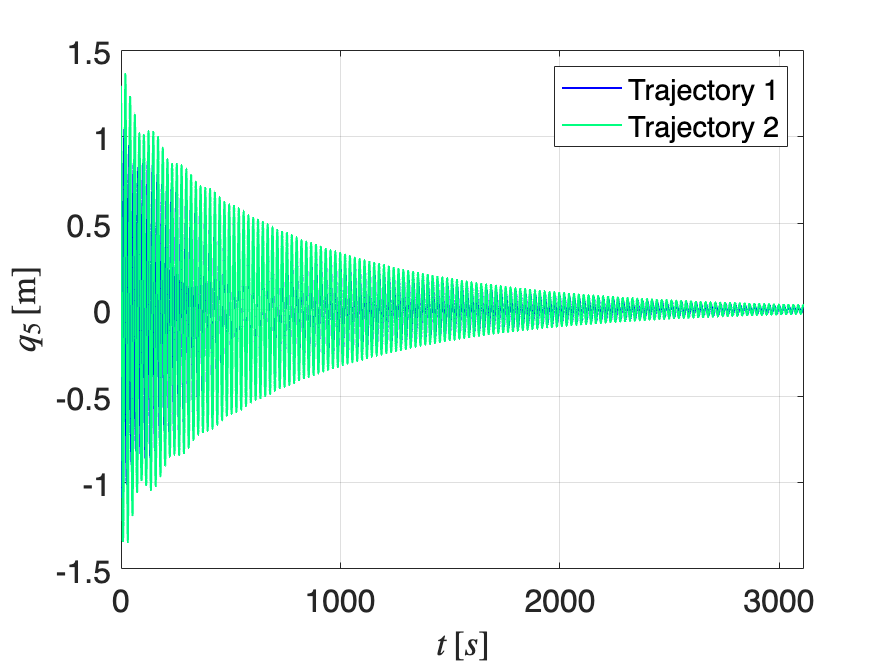



customFigure(); colororder(winter(nTraj));
for iTraj = 1:size(yData,1)
    plot(yData{iTraj,1}, yData{iTraj,2}(n,:),'Linewidth',1,'Displayname',['Trajectory ' num2str(iTraj)])
end
xlim([0 endTime])
xlabel('$t \, [s]$','Interpreter','latex'); 
ylabel('$q_5 \, [$m$]$','Interpreter','latex'); 
legend('location','NE')

Check whether we are close to the manifold using a spectrogram. 

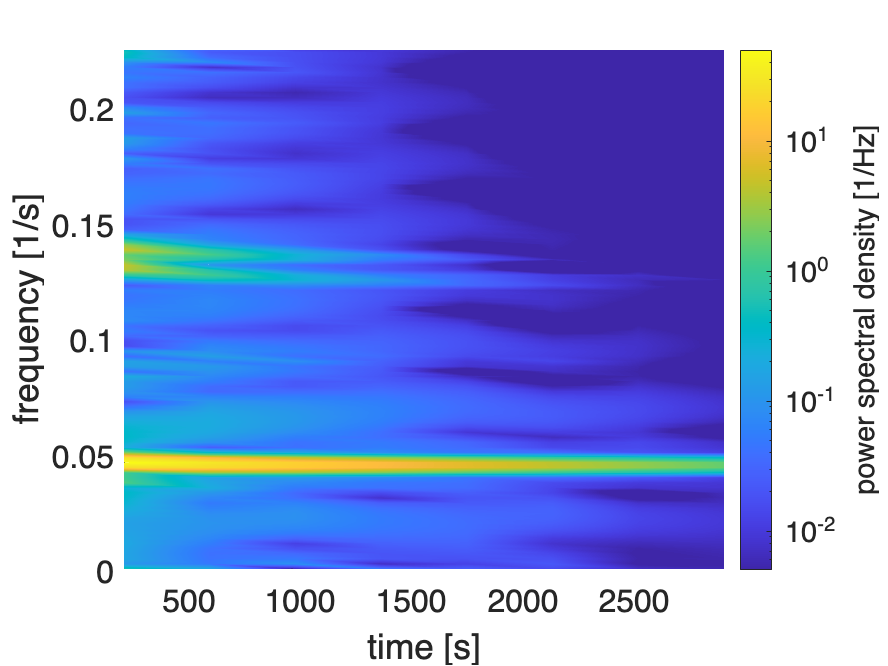

hold on;

showSpectrogram(yData(1,:), 1);
ylim([0, abs(lambda(1))/2/pi*5]);

Based on the spectrogram, we should truncate the initial transients. 

sliceInt = [500.0, Inf];
yDataTrunc = sliceTrajectories(yData, sliceInt);


## Datadriven manifold fitting

The measured trajectories are assumed to lie close to a two-dimensional manifold that is tangent at the origin to the eigenspace corresponding to the slowest pair of eigenvalues. We now want to fit a  polynomial of order $n_{\textrm{SSM}}$ to the data points to approximate the manifold. 

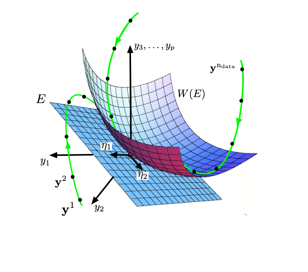

Here we use a graph style parametrization, meaning that the manifold is parametrized using coordinates in the spectral subspace $E$. Let us write down a basis  for $E$ as $V=\left\lbrack \textrm{Real}\;\left({\mathit{\mathbf{v}}}_1 \right),\textrm{Imagl}\;\left({\mathit{\mathbf{v}}}_1 \right)\right\rbrack$, which we assume to be unknown now. 

The **coordinate chart **is a projection to $E$: $\eta =V^T Y$

The **parametrization **is a graph over E:

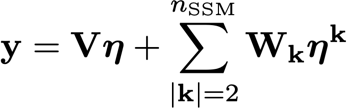

We now seek the coefficients ${\mathit{\mathbf{W}}}_{\mathit{\mathbf{k}}}$ of the monomial terms ${\eta \;}^{\mathbf{k}} ={\eta \;}_1^{k_1 } \eta {\;}_2^{k_2 }$. This optimization problem amounts to a constrained minimization of a cost function computed from the measured data $y_k$,

The minimization is performed with the Matlab routine `fmincon` in `IMGeometry`.

SSMOrder = 3; SSMDim = 2;
[IMInfo, SSMChart, SSMFunction] = IMGeometry(yDataTrunc(indTrain,:), SSMDim, SSMOrder);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    6.506028e-07    1.110e-15    1.952e-05
    1       2    6.500011e-07    4.408e-10    1.920e-05    2.459e-05
    2       3    6.471341e-07    1.073e-08    1.762e-05    1.215e-04
    3       4    6.359792e-07    2.371e-07    1.024e-05    5.719e-04
    4       5    6.247598e-07    1.355e-06    1.076e-05    1.370e-03
    5       6    6.245562e-07    2.802e-10    1.080e-05    2.541e-05
    6       7    6.235381e-07    1.834e-09    1.069e-05    8.599e-05
    7       8    6.188982e-07    4.090e-08    1.009e-05    4.138e-04
    8       9    6.049219e-07    8.004e-07    1.000e-05    1.839e-03

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


## Plot and validation

Now that we have computed the eigenspace of the manifold, we pass to the reduced coordinates $y$ by projecting all trajectories onto the eigenspace and plot the SSM. 

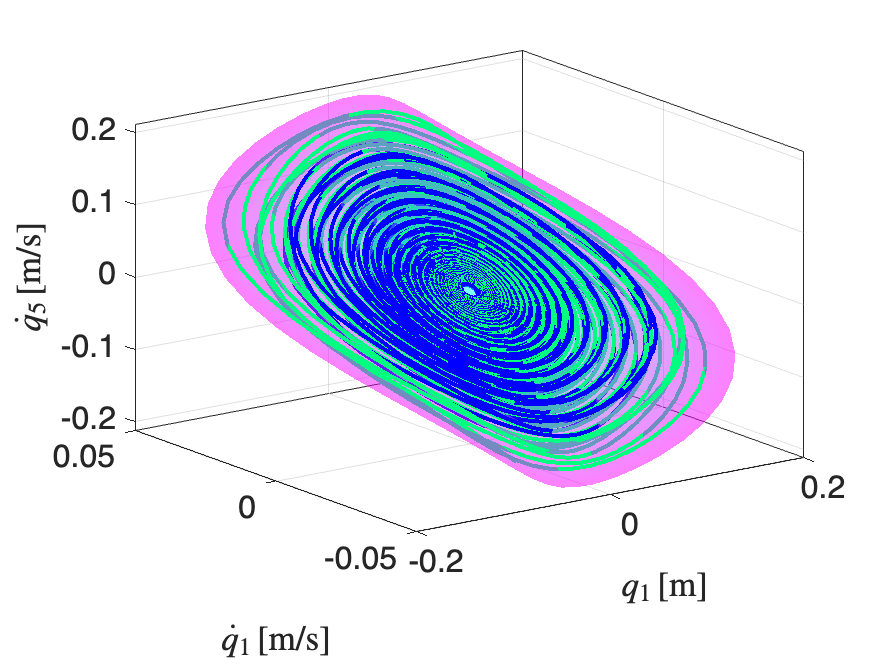

etaData = projectTrajectories(IMInfo, yDataTrunc);
coordPlot = [1 n+1 2*n];
plotSSMandTrajectories(IMInfo, coordPlot, yDataTrunc,etaData,'Margin',10,'ColorTraj', winter(nTraj));
xlabel('$q_1 \, [$m$]$','Interpreter','latex'); 
ylabel('$\dot{q}_1 \, [$m/s$]$','Interpreter','latex'); 
zlabel(['$\dot{q}_{' num2str(n) '} \, [$m/s$]$'],'Interpreter','latex'); legend('off')

## Reduced order model

We compute a model for the reduced dynamics with the truncated training data projected onto the manifold. The time derivative of the reduced coordinate is approximated via finite differences. The reduced dynamics are sought in normal form, which means that we simultaneously seek a coordinate transformation $\eta =\mathit{\mathbf{T}}\left(\mathbf{z}\right)$ and the reduced vector field 

$\dot{\;\mathbf{z}} =\mathbf{R}\left(\mathbf{z}\right)$.

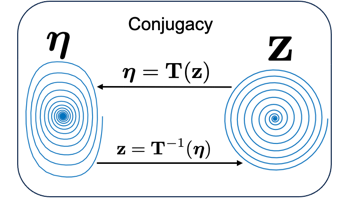

The transformation $\mathbf{T}$ and the dynamics are both represented by polynomial maps and are obtained by an optimization procedure

which is done by the `IMDynamicsFlow` function. Note that the matrix ${\mathit{\mathbf{R}}}_0$ is diagonal, and hence the coordinates are complex in general $\mathit{\mathbf{z}}\in C$.

The vector field in normal form is radially symmetric in this case, which means polar coordinates can be introduced as $\rho =|z|$ and $\theta =\textrm{Arg}\left(z\right)\ldotp$ The polar normal form of the dynamics for this 2D SSM case has the form

$\dot{\rho} = c(\rho)\rho$ ,

$\dot{\theta} =  \omega(\rho)$.

This is returned automatically by `IMDynamicsFlow` if the 'normalform' style is specified.

ROMOrder = 3;
RDInfo = IMDynamicsFlow(etaData(indTrain,:), ...
    'R_PolyOrd', ROMOrder, ...
    'style', 'normalform');

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1      1.44097e-06                      3.69e-05
     1           5      5.96336e-07            820        3.7e-05  
     2           6      2.43657e-07              1        3.8e-05  
     3           7      1.90305e-08              1       7.03e-06  
     4           8      5.33073e-09              1        1.4e-06  
     5           9      4.43465e-09              1       3.52e-07  
     6          10       4.3229e-09              1       2.35e-07  
     7          11      4.23859e-09              1       1.75e-07  
     8          12      4.23514e-09              1       2.47e-07  
     9          13      4.22996e-09              1       2.05e-08  
    10          14      4.22963e-09              1       1.71e-08  
    11          15

We transform the truncated initial condition of our test trajectory according to the obtained change of coordinates, and iterate our reduced order evolution rule to predict the development of the trajectory.

[yRec, etaRec, zRec] = advect(IMInfo, RDInfo, yDataTrunc);

## Evaluation of the reduced dynamics

The error RRMSE is computed as the average distance of the predicted trajectory to the measured one in the full state space. We also plot the testing trajectory.

% Compute errors
normedTrajDist = computeTrajectoryErrors(yRec, yDataTrunc);
RRMSE = mean(normedTrajDist(indTest))

RRMSE = 0.0084


% Plot trajectories
plotReducedCoordinates(etaData(indTest,:), etaRec(indTest,:))
legend({'Test set', 'Prediction'})
plotTrajectories(yDataTrunc(indTest,:), yRec(indTest,:), 'm', n, {'Test set', 'Prediction'})
xlabel('$t \, [s]$','Interpreter','latex'); 
ylabel('$q_5 \, [$m$]$','Interpreter','latex'); 

% Check eigenvalues
reconstructedEigenvalues = RDInfo.eigenvaluesLinPartFlow;
[lambda(1) reconstructedEigenvalues(1)]

ans =   -0.0012 + 0.2825i  -0.0012 + 0.2827i


## Backbone curves and frequency response curves

We can now study the reduced order model. We extract backbones curves and forced response curves (FRCs). The backbone curve is an instantaneous relationship between frequency and amplitude and can be simple read off the polar normal form as $B=\left\lbrace \left(\rho \;,\omega \;\left(\rho \;\right)\right)\right\rbrace$. For the FRC prediction, our reduced dynamics are modified as


$$\dot{\;\mathbf{z}} =\mathbf{R}\left(\mathbf{z}\right)+f_{\mathrm{red}} e^{i\Omega \;t}$$


where $$\Omega$ is the forcing frequency and $$f_{red}$ is the forcing amplitude in the reduced model. In polar coordinates, after introducing the phase difference $\Psi =\theta -\Omega \;t$, we obtain 

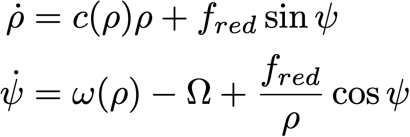

The fixed points of this planar system correspond to periodic orbits of the forced system, i.e., they define the forced response curve (FRC).

For FRC extraction, we may use the analytical solution. For a forcing frequency $\Omega \;$we have a periodic orbit of amplitude $\rho^*$, where 

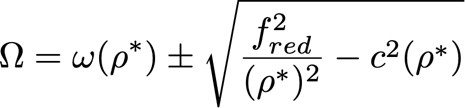

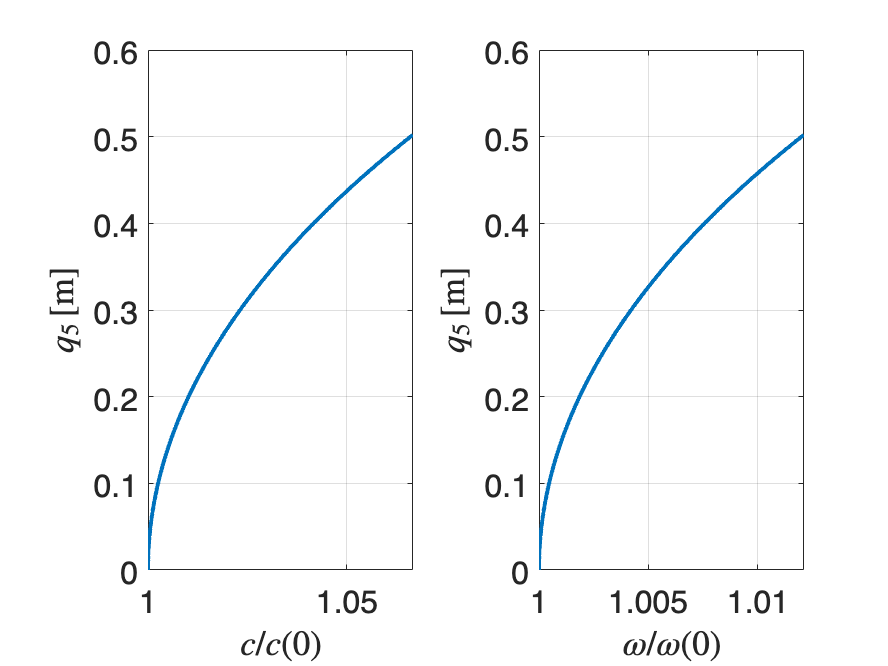

% Define the physical amplitude metric
amplitudeFunction = @(x) x(n,:);
maxRho = max(abs(zRec{1,2}(1,:)));

% Compute backbone curves in the training range of data
BBCInfo = backboneCurves(IMInfo, RDInfo, amplitudeFunction, maxRho, 'norm');
subplot(121);
ylabel('$q_5 \, [$m$]$','Interpreter','latex'); 
subplot(122);
ylabel('$q_5 \, [$m$]$','Interpreter','latex'); 


% Compute frequency response curves
omegaSpan = [0.95 1.05]*abs(reconstructedEigenvalues(1)); 
amplitudeCal = [0.0732 0.177 0.331 0.5]; forcingSpan = zeros(1,length(amplitudeCal));
for iCal = 1:length(amplitudeCal)
   [~,pos] = min(abs(BBCInfo.amplitude-amplitudeCal(iCal)));
   forcingSpan(iCal) = -BBCInfo.amplitudeNormalForm(pos)*BBCInfo.damping(pos);
end
[IMInfoF,RDInfoF] = forcedSSMROM(IMInfo,RDInfo,'nForcingFrequencies',1);

Forced SSM reduced-order model assumes external forcing only along the tangent (modal) subspace at the origin. 


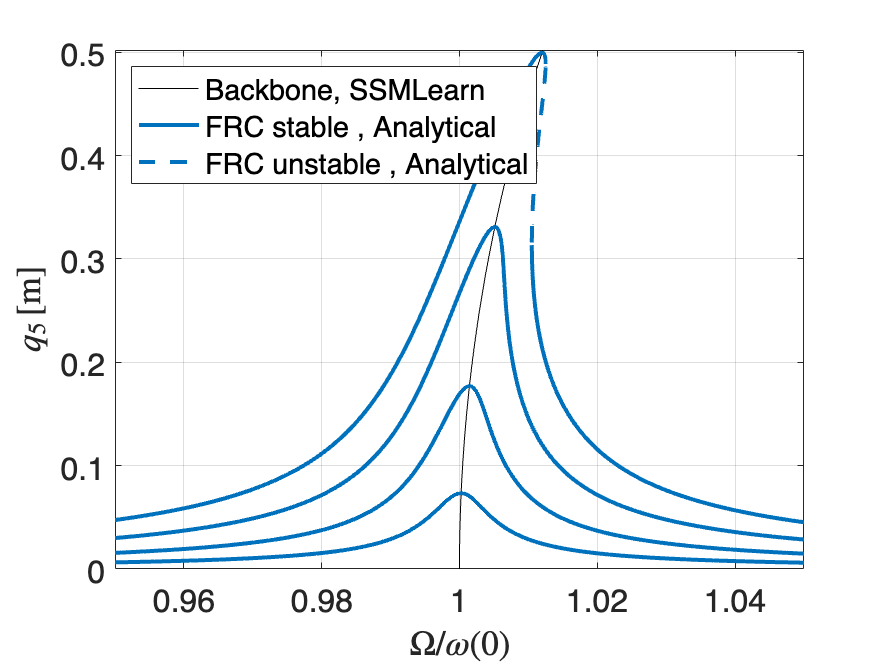

FRCData = analyticalFRC(IMInfoF,RDInfoF,forcingSpan,amplitudeFunction);

freqNorm = BBCInfo.frequency(1);
% Plot backbone curves and FRCs
customFigure(); colors = colororder;
plot(BBCInfo.frequency/freqNorm, BBCInfo.amplitude,'k','DisplayName','Backbone, SSMLearn')
plotFRC(FRCData, colors(1,:), ', Analytical','freqscale',freqNorm)
%plotFRC(FRCDataCOCO, colors(2,:), ', Numerical','freqscale',freqNorm)
xlim(omegaSpan/freqNorm)
ylim([0 max(BBCInfo.amplitude)])
xlabel('$\Omega/\omega(0)$','Interpreter','latex'); 
ylabel('$q_5 \, [$m$]$','Interpreter','latex'); 
legend('location','NW')